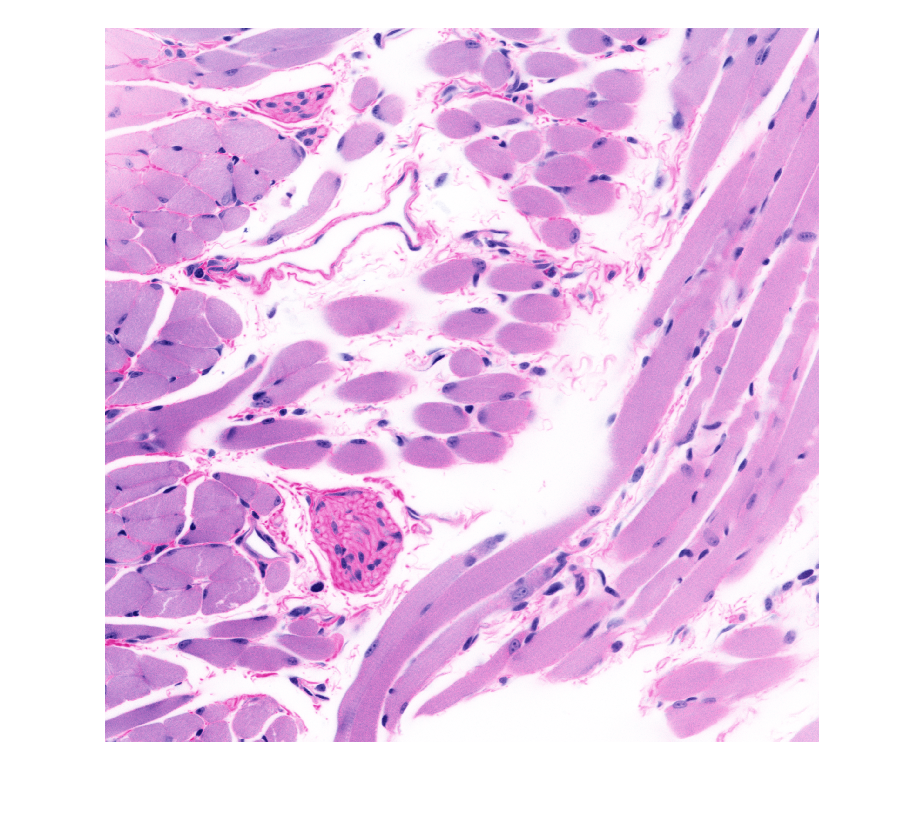

% this script can extract each z plane
% then perform colour transfer to 5 images
% import tiff
source_image_path = strrep("D:\Nick\3D HnE\20240413 data preparation\tongue muscle source\tongue_muscle_tiff.tiff", '\', '/');
num_frame = numel(imfinfo(source_image_path));
source_stack = cell(num_frame, 1);
for i = 1:num_frame
    source_stack{i, 1} = double(imread(source_image_path, 'Index', i)) / 255;
end
figure;
imshow(source_stack{1, 1});

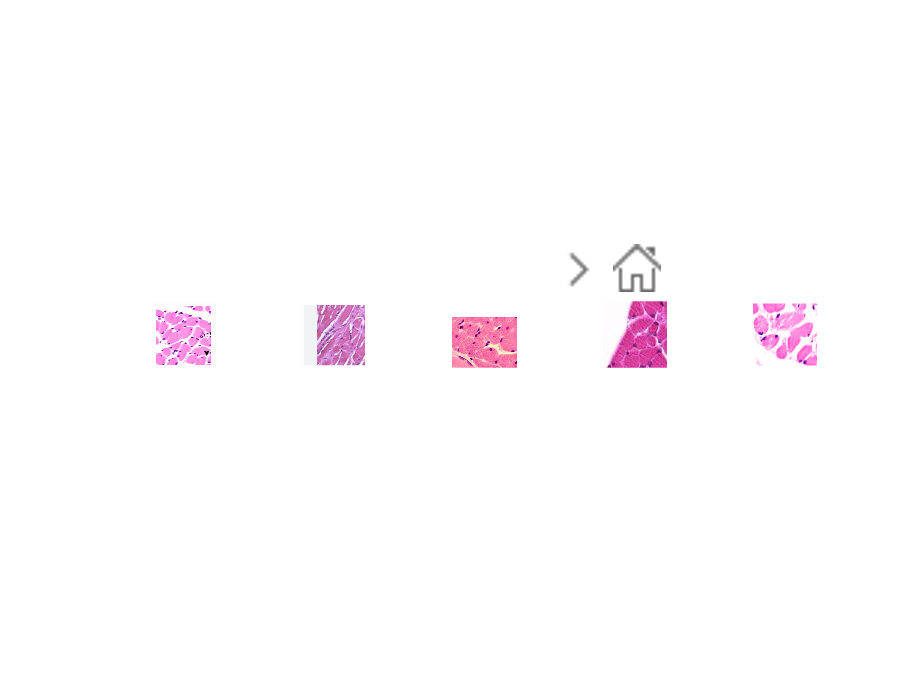

% import colour transfer target images
target_image_path = strrep("D:\Nick\3D HnE\20240413 data preparation\tongue muscle source\tongue_muscle_example", '\', '/');
num_target = 5;
target_stack = cell(num_target, 1);
for i = 1:num_target
    temp_path = sprintf('%s_%d.png', target_image_path, i);
    target_stack{i, 1} = double(imread(temp_path)) / 255;
end
figure;
for i = 1:5
    subplot(1, 5, i);
    imshow(target_stack{i, 1});
end

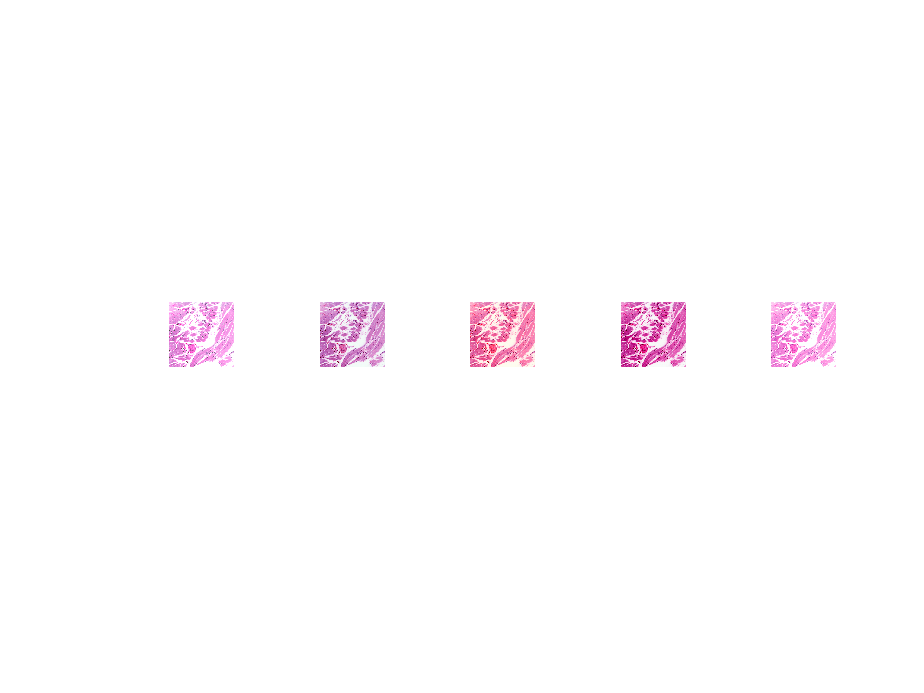

% try colour transfer
image_try = source_stack{1, 1};
for i = 1:5
    transformed_image = colour_transfer_MKL(image_try, target_stack{i, 1});
    subplot(1, 5, i);
    imshow(transformed_image);
end

% create dataset
folder_path = strrep("D:\Nick\3D HnE\20240413 data preparation\tongue muscle colour transfer", '\', '/');
for i = 1:num_frame
    source_plane = source_stack{i, 1};
    for j = 1:5
        transformed_image = colour_transfer_MKL(source_plane, target_stack{j, 1});
        imwrite(transformed_image, sprintf('%s/%d_%d.png', folder_path, i, 4 * j - 3));
        imwrite(transformed_image, sprintf('%s/%d_%d.png', folder_path, i, 4 * j - 2));
        imwrite(transformed_image, sprintf('%s/%d_%d.png', folder_path, i, 4 * j - 1));
        imwrite(transformed_image, sprintf('%s/%d_%d.png', folder_path, i, 4 * j));
    end
end